# Plant Model

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');

Unrecognized function or variable 'commonPath'.

latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Globals

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

# Input Signals

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Export_Fig

%This toggles the exportfig commands throughout this file.  1 enables, 0
%disables.
figurePath = strcat(commonPath,'\Golden Figures\');

eftoggle = 1;


# Hybrid Model

%Model Setup
delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize) %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# I for nondim

rat_I = 4.971;

# rad to deg

r2deg = 180/pi;

# Typical Hybrid Response

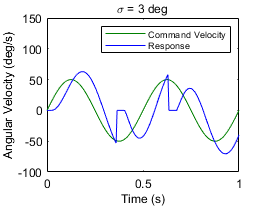

K_P = 15;
K_I = 250;
switch_thresh = 3*(pi)/180;
sac_time = 0.04;
n_delay = 0.021;

sinin = pureSin(20,:);
V_in = [pureSinTime' sinin'];

output = sim(simName,'SrcWorkspace','current');
out = output.V_out';


figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.75 2.1422])
pos = get(gcf,'pos');
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 150])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Arial','FontSize',9,'Color','k')
ylabel('Angular Velocity (deg/s)','FontName','Arial','FontSize',9)
legend('Command Velocity','Response','FontName','Arial','FontSize',7,'EdgeColor','k')
title('\sigma = 3 deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\TypicalHybridResponse');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    %print(gcf,savePath,'-dpdf','-loose')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

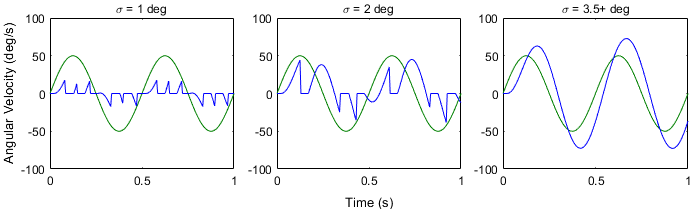


%figure('Renderer', 'painters', 'Position', [10 10 1500 450])
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 7.25 2.1808])
pos = get(gcf,'pos');
tl = tiledlayout(1,3, 'Padding', 'none', 'TileSpacing', 'compact');

switch_thresh = 1*pi/180;
output = sim(simName,'SrcWorkspace','current');
out = output.V_out';

nexttile
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 100])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
title('\sigma = 1 deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

switch_thresh = 2*pi/180;
output = sim(simName,'SrcWorkspace','current');
out = output.V_out';

nexttile
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 100])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
title('\sigma = 2 deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

switch_thresh = 3.5*(pi)/180;
output = sim(simName,'SrcWorkspace','current');
out = output.V_out';

nexttile
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 100])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
title('\sigma = 3.5+ deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

xlabel(tl,'Time (s)','FontName','Arial','FontSize',10,'Color','k')
ylabel(tl,'Angular Velocity (deg/s)','FontName','Arial','FontSize',10,'Color','k')

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\HybridResponseCombine');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

%clear K_P K_I td switch_thresh sac_time n_delay sinin V_in

# Stability Plots

%figure('Renderer', 'painters', 'Position', [10 10 1500 460])
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 7.25 3])
pos = get(gcf,'pos');
tl = tiledlayout(1,3, 'Padding', 'none', 'TileSpacing', 'compact');
xlabel(tl,'Real Axis','FontName','Arial','FontSize',10,'Color','k')
ylabel(tl,'Imaginary Axis','FontName','Arial','FontSize',10,'Color','k')

## Nyquist (Delay)

nexttile
%PI controller
Kp = 10;
Ki = 200;
C_tf = tf([Kp Ki],[1 0]);

%Delay
td = [0.04 0.058 0.065];
linecolors = [{'k'} {'b'} {'r'}];
hold on
w = logspace(0,11,1000);
for i = 1:size(td,2)
    %Delay (Pade approximation)
    [nump,denp]=pade(td(i),3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    
end
plot(-1,0,'r+')
xlim([-2,.25])
ylim([-1.5,1.5])
yline(0,':k');
xline(0,':k');
xline(-1,'r--');
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'Delay = 40 ms (Stable)','Delay = 58 ms (M. Stable)',...
    'Delay = 65 ms (Unstable)'},'FontName','Arial','FontSize',8,'EdgeColor','k','Location','northoutside')
title('K_P^* = 10, K_I^* = 200','FontName','Arial','FontSize',8,'Color','k','FontWeight','normal')
box on

## Nyquist (Proportional Gain)

nexttile
%PI controller
Kp = [10 38 45];
Ki = 200;

%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
hold on
w = logspace(0,11,1000);
for i = 1:size(Kp,2)
    C_tf = tf([Kp(i) Ki],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    
end
plot(-1,0,'r+')
xlim([-1.5,.5])
ylim([-1.5,1.5])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_P^* = 10 (Stable)','K_P^* = 38 (M. Stable)'...
    ,'K_P^* = 45 (Unstable)'},'FontName','Arial','FontSize',8,'EdgeColor','k','Location','northoutside')
title('K_I^* = 200, Delay = 40 ms','FontName','Arial','FontSize',8,'Color','k','FontWeight','normal')
box on

## Nyquist (Integral Gain)

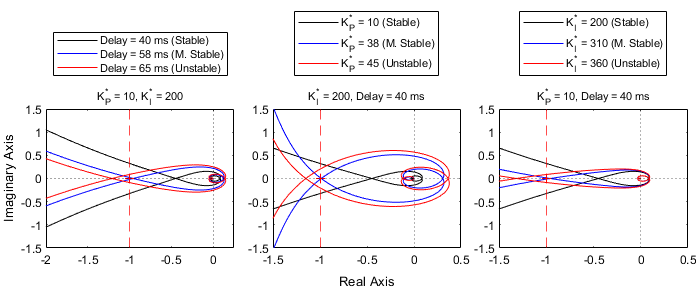

nexttile
%PI controller
Kp = 10;
Ki = [200 310 360];

%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
hold on
w = logspace(0,11,1000);
for i = 1:size(Ki,2)
    C_tf = tf([Kp Ki(i)],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    
end
plot(-1,0,'r+')
xlim([-1.5,.5])
ylim([-1.5,1.5])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_I^* = 200 (Stable)','K_I^* = 310 (M. Stable)'...
    ,'K_I^* = 360 (Unstable)'},'FontName','Arial','FontSize',8,'EdgeColor','k','Location','northoutside')
title('K_P^* = 10, Delay = 40 ms','FontName','Arial','FontSize',8,'Color','k','FontWeight','normal')
box on

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\NyquistCombined');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

## Delay Stability Surface

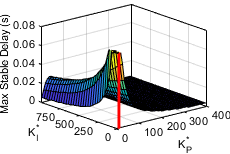

%Smooth Stability Data
inputPath = strcat(commonPath,'\Stability Sweep Data\');
latestStability = latestTimeParse(inputPath,'stabilitySweep');
load(latestStability)


sf = fit([stabletip(:,1), stabletip(:,2)],stabletip(:,3),'cubicinterp');
%figure('Renderer', 'painters', 'Position', [10 10 1000 700])
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.4 1.6])
pos = get(gcf,'pos');

set(gcf, 'Color', 'w');
plot(sf)
% hold on
% scatter3(stabletip(:,1)/rat_I, stabletip(:,2)/rat_I, stabletip(:,3),1,'o')
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial'; 
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 8;
ax.ZAxis.FontName = 'Arial';
ax.ZAxis.Color = 'k';
xlabel('K_P^*','FontName','Arial','FontSize',8)
ylabel('K_I^*','FontName','Arial','FontSize',8)
posx = ax.YLabel.Position;
ax.YLabel.Position = [posx(1:2) -0.01];
posy = ax.XLabel.Position;
ax.XLabel.Position = [posy(1:2) -0.01];
zlabel('Max Stable Delay (s)','FontName','Arial','FontSize',8)
box on
hold on
r=4;

[X,Y,Z] = cylinder(r,50);
X = X + 10;
Z = Z*0.08;
h=surf(X,Y,Z,'FaceColor',[1 0 0],'EdgeColor',[1 0 0]);

xlim([0 400]) %400
ylim([0 1000]) %1000
zlim([0 0.08]) %.08

p = get(gca,'Position');
set(gca,'Position',[p(1) p(2)+0.05 p(3) p(4)]);
xticks([0 100 200 300 400])
yticks([0 250 500 750])
xtickangle(0)
ytickangle(0)

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

view(-40,25)
savePath =strcat(figurePath,'\Smooth Stability\MaxStableDelayLeft');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

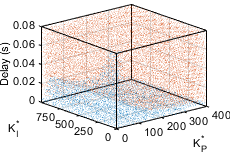



%figure('Renderer', 'painters', 'Position', [10 10 1000 700])
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.4 1.6])
pos = get(gcf,'pos');

set(gcf, 'Color', 'w');
stable = stable(1:10:end,:);
unstable = unstable(1:10:end,:);
scatter3(stable(:,1), stable(:,2), stable(:,3),0.01,'o')
hold on
scatter3(unstable(:,1), unstable(:,2), unstable(:,3),0.01,'o')
ax = gca;
ax.BoxStyle ='full';
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 8;
ax.ZAxis.FontName = 'Arial';
ax.ZAxis.Color = 'k';
xlabel('K_P^*','FontName','Arial','FontSize',8)
ylabel('K_I^*','FontName','Arial','FontSize',8)
posx = ax.YLabel.Position;
ax.YLabel.Position = [posx(1:2) -0.01];
posy = ax.XLabel.Position;
ax.XLabel.Position = [posy(1:2) -0.01];
zlabel('Delay (s)','FontName','Arial','FontSize',8)
box on
xlim([0 400])
ylim([0 1000])
zlim([0 0.08])

p = get(gca,'Position');
set(gca,'Position',[p(1) p(2)+0.05 p(3) p(4)]);
xticks([0 100 200 300 400])
yticks([0 250 500 750])
xtickangle(0)
ytickangle(0)

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

view(-40,25)
savePath =strcat(figurePath,'\Smooth Stability\StabilityCloud');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

## 0.021 Delay Slice

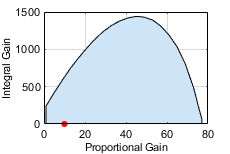

iter = 1;
iterM = 1;
for i = 1:size(stabletip,1)
    if stabletip(i,3) >= 0.021
        stableSliceMax(iterM,:) = stabletip(i,:);
        if iterM == 1
            iterM = iterM + 1;
        else
            if stableSliceMax(iterM,1) ~= stableSliceMax(iterM-1,1)
                iterM = iterM + 1;
            else
                stableSliceMax(iterM-1,:) = stabletip(i,:);
            end 
        end
        
    end
end
stableSliceMax = stableSliceMax(1:end-1,:);
fKp = [stableSliceMax(1,1) 0 stableSliceMax(1,3)];
lKp = [stableSliceMax(end,1) 0 stableSliceMax(end,3)];
stableSliceMax = [fKp;stableSliceMax;lKp];

%figure('Renderer', 'painters', 'Position', [10 10 1000 700])
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.4 1.6])
pos = get(gcf,'pos');

a = area(stableSliceMax(:,1),stableSliceMax(:,2),'FaceColor','#CEE4F7');
%a.FaceAlpha = 0.2;
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
xlabel('Proportional Gain','FontName','Arial','FontSize',8)
ylabel('Integral Gain','FontName','Arial','FontSize',8)
%title('Stable Region for Delay of 40ms','FontName','Arial','FontSize',22,'FontWeight','bold')
grid on
hold on
plot(10,0.1,'.r','MarkerSize',15)
xlim([0 80])

basepath = strcat(commonPath,'\Stability Sweep Data');
savePath = genFileName(basepath,'04DelaySlice');
save(savePath,'stableSliceMax');

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\DelaySlice');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

# Hybrid and Smooth Swept Performance

clearvars -except commonPath
%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');

%This part is just to get the structure to populate an empty version for
%filling. 
latestSweep = latestTimeParse(inputPath,'megaSweep_1'); 
load(latestSweep)
sweepData = repmat(sweepData(1,1),size(sweepData,1),size(sweepData,1),size(sweepData,2));

for i = 1:1:size(sweepData,1)
   tic
   latestSweep = latestTimeParse(inputPath,strcat('megaSweep_',num2str(i))); 
   T = load(latestSweep);
   sweepData(i,:,:) = T.sweepData;
   clear T
   toc
end

Elapsed time is 6.501411 seconds.
Elapsed time is 10.225848 seconds.
Elapsed time is 9.783984 seconds.
Elapsed time is 9.668800 seconds.
Elapsed time is 11.097429 seconds.
Elapsed time is 9.366229 seconds.
Elapsed time is 9.025333 seconds.
Elapsed time is 10.030005 seconds.
Elapsed time is 9.226956 seconds.
Elapsed time is 8.938803 seconds.
Elapsed time is 8.906135 seconds.
Elapsed time is 9.471807 seconds.
Elapsed time is 10.101481 seconds.
Elapsed time is 10.925672 seconds.
Elapsed time is 9.477241 seconds.
Elapsed time is 9.452623 seconds.
Elapsed time is 11.728611 seconds.
Elapsed time is 9.190130 seconds.
Elapsed time is 10.969193 seconds.
Elapsed time is 9.390866 seconds.
Elapsed time is 17.001175 seconds.
Elapsed time is 10.964614 seconds.
Elapsed time is 9.614486 seconds.
Elapsed time is 9.693753 seconds.
Elapsed time is 13.805045 seconds.
Elapsed time is 10.567426 seconds.
Elapsed time is 8.937111 seconds.
Elapsed time is 13.512851 seconds.
Elapsed time is 8.815902 seconds.
El

eftoggle = 0;
clear inputPath latestSweep

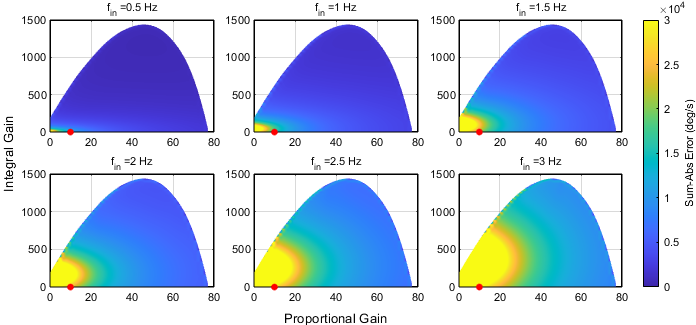

eftoggle=1;
SlicePerformance(sweepData,commonPath,'sSAE',0,eftoggle,0)

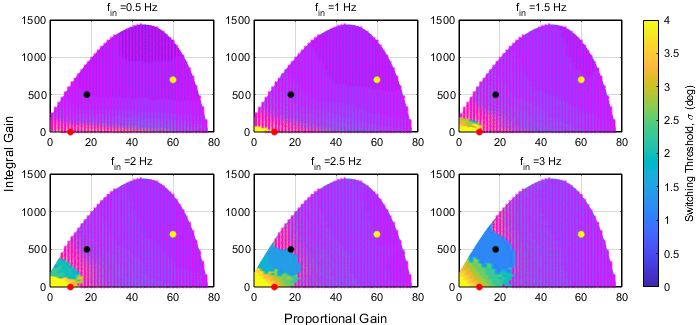

sigmaInd = 4;
SlicePerformance(sweepData,commonPath,'hSigmaSAEPurp',sigmaInd,eftoggle,25)

% [bestsSAE,errsSAE] = optimalSet(sweepData,commonPath,'sSAE');
% [besthSAE,errshSAE] = optimalSet(sweepData,commonPath,'hSAE');
[~,~] = optimalSet(sweepData,commonPath,'mixSAE',eftoggle);

# Detailed look at Performance at KP* = 10, KI*  = 0

clearvars -except commonPath
%figure('Renderer', 'painters', 'Position', [10 10 1500 700])
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 7.25 3.3833])
pos = get(gcf,'pos');
tl = tiledlayout(2,3,'Padding','none', 'TileSpacing', 'compact');
%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');
latestSweep = latestTimeParse(inputPath,'megaSweep_10_1'); 
load(latestSweep)

sigs = [0.5 1 3 6].*(pi/180);

nexttile
[ftraces1,saetraces1] = fsigmaplot(sweepData,switchThresh,sinfreqsDecimate,sigs);
view(-35,20)

# Detailed look at Performance at KP* = 18, KI*  = 500

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');
latestSweep = latestTimeParse(inputPath,'megaSweep_18_1'); 
load(latestSweep)

nexttile
[ftraces2,saetraces2] = fsigmaplot(sweepData,switchThresh,sinfreqsDecimate,sigs);
view(-35,20)


# Detailed look at Performance at KP* = 60, KI*  = 700

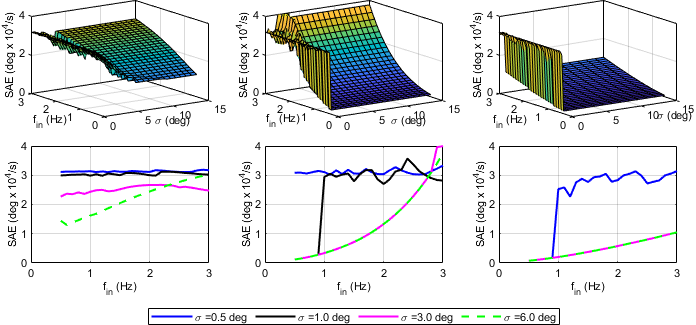

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');
latestSweep = latestTimeParse(inputPath,'megaSweep_60_1'); 
load(latestSweep)
eftoggle = 1;

nexttile
[ftraces3,saetraces3] = fsigmaplot(sweepData,switchThresh,sinfreqsDecimate,sigs);
%view(25,20)
view(-35,20)

nexttile
ax1 = fsae2d(ftraces1,saetraces1,sigs,0);
nexttile
ax2 = fsae2d(ftraces2,saetraces2,sigs,0);
nexttile
ax3 = fsae2d(ftraces3,saetraces3,sigs,0);

lg  = legend(ax1,'Orientation','Horizontal','NumColumns',5,'FontName','Arial','FontSize',8,'EdgeColor','k'); 
lg.Layout.Tile = 'South'; % <-- Legend placement with tiled layout

basepath = strcat(commonPath,'\Golden Figures\Hybrid Performance\');
savePath = strcat(basepath,'hSAEdet','.pdf');

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

if eftoggle == 1
    %export_fig (savePath,'-pdf','-nocrop')
    exportgraphics(gcf,savePath)
end

clearvars -except commonPath
%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');

%This part is just to get the structure to populate an empty version for
%filling.
latestSweep = latestTimeParse(inputPath,'megaSweep_disc_1'); 
load(latestSweep)
sweepData = repmat(sweepData(1,1),size(sweepData,1),size(sweepData,1),size(sweepData,2));

for i = 1:1:size(sweepData,1)
   tic
   latestSweep = latestTimeParse(inputPath,strcat('megaSweep_disc_',num2str(i))); 
   T = load(latestSweep);
   sweepData(i,:,:) = T.sweepData;
   clear T
   toc
end

Elapsed time is 0.043035 seconds.
Elapsed time is 0.043105 seconds.


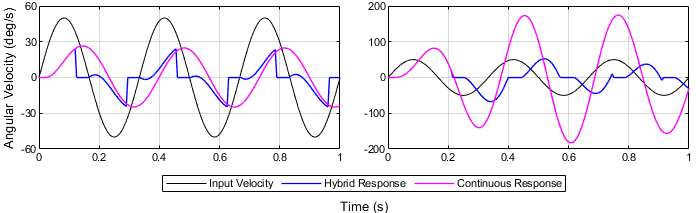

clear inputPath latestSweep

[pos] = responseCurves(sweepData,...
    Ki,Kp,switchThresh,sinfreqsDecimate,pureSinTime,[10 10],[0 500],[0.05 0.04],[3 6]);
basepath = strcat(commonPath,'\Golden Figures\Hybrid Performance\');
savePath = strcat(basepath,'disctraces','.pdf');
eftoggle = 1;

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

if eftoggle == 1
    %export_fig (savePath,'-pdf','-nocrop')
    exportgraphics(gcf,savePath)
end

# Hybrid Stability

Elapsed time is 0.147872 seconds.


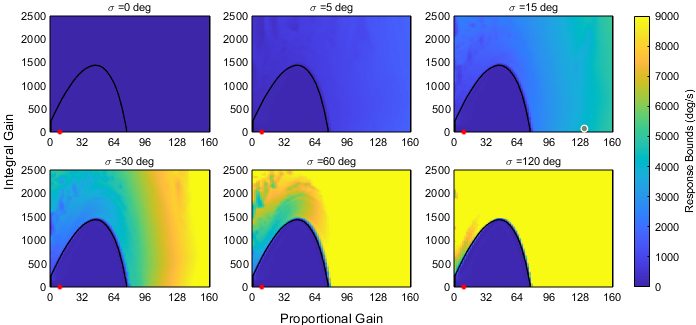

clearvars -except commonPath
eftoggle = 1;
%Load portion Hybrid Stability data
hStabPath = strcat(commonPath,'\Hybrid Stability Results\');
latestStab = latestTimeParse(hStabPath,'stabSweepstiff');
tempFile = matfile(latestStab);
stabData4= tempFile.stabData(:,4);
stabData5= tempFile.stabData(:,5);
stabDataABS = abs(stabData5-stabData4);
clear stabData4 stabData5
stabDataSmall = tempFile.stabData(:,1:3);
stabDataStiffFinal = [stabDataSmall stabDataABS];
clear stabDataSmall stabDataABS
sigmaS = tempFile.sigma;

latestStab = latestTimeParse(hStabPath,'stabSweeploose');
tempFile = matfile(latestStab);
stabData4= tempFile.stabData(:,4);
stabData5= tempFile.stabData(:,5);
stabDataABS = abs(stabData5-stabData4);
clear stabData4 stabData5
stabDataSmall = tempFile.stabData(:,1:3);
stabDataLooseFinal = [stabDataSmall stabDataABS];
clear stabDataSmall stabDataABS
sigma = [tempFile.sigma sigmaS];

inc = 1;
stabDatafFinal = stabDataStiffFinal;
for i =1:6:(size(stabDataStiffFinal,1)+size(stabDataLooseFinal,1))
    if i == 1
        stabDatafFinal = [stabDataLooseFinal(inc,:) ; stabDatafFinal];    
    else
        stabDatafFinal = [stabDatafFinal(1:(i-1),:) ; stabDataLooseFinal(inc,:) ; stabDatafFinal(i:end,:)]; 
    end
    inc = inc + 1;
end
sigs = (pi/180)*[0.02 5 15 30 60 120];
stabPlot(stabDatafFinal,sigs,sigma,commonPath,eftoggle);

# Bode Plots for margins

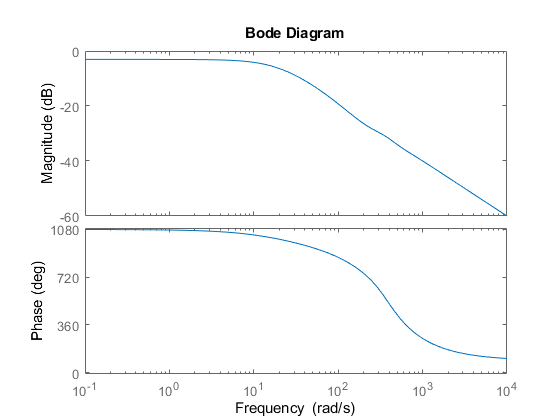

clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant);
eftoggle = 1;

%PI controller
Kp = 10;
Ki = 0;

C_tf = tf([Kp Ki],[1 0]);

%Delay (Pade approximation)
td =0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = d_tf*C_tf*G_plant;
den = (1 + num);
cl_tf = num/den;
num=minreal(num);

[mag1,phase1,wout1] = bode(num);
figure
bode(cl_tf)

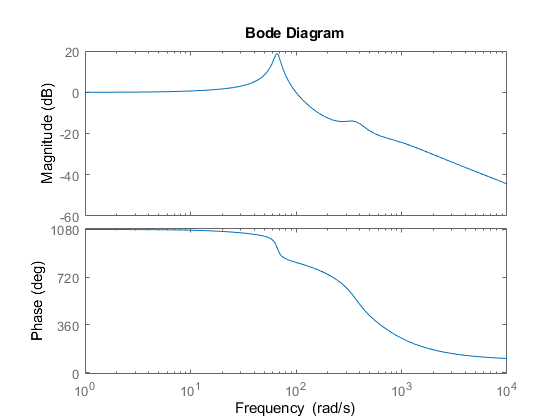

[Gm1,Pm1,Wcg1,Wcp1] = margin(num);

%PI controller
Kp = 60;
Ki = 700;

C_tf = tf([Kp Ki],[1 0]);

%Delay (Pade approximation)
td =0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = d_tf*C_tf*G_plant;
den = (1 + num);
cl_tf = num/den;
num = minreal(num);

[mag2,phase2,wout2] = bode(num);
figure
bode(cl_tf)

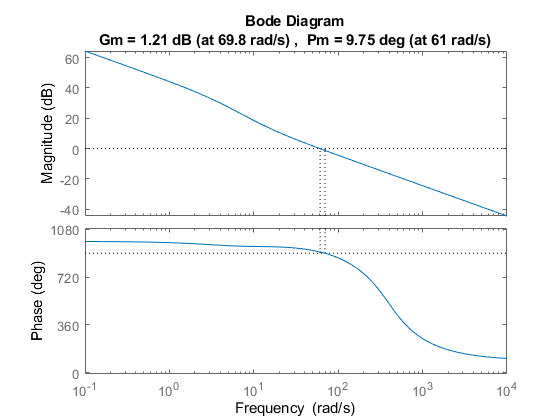

[Gm2,Pm2,Wcg2,Wcp2] = margin(num);
figure
margin(num)

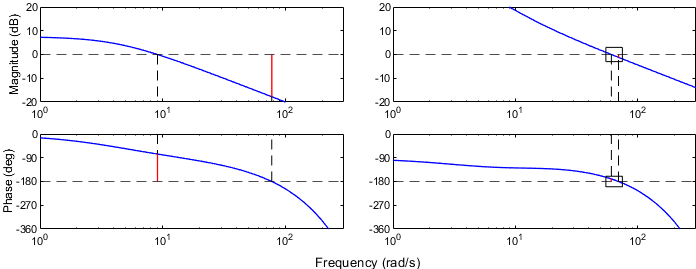

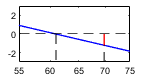

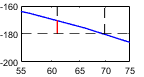


insetg = [55 -3 20 6]; %34.5 to 40 x , -1.25 to 0.5 y
insetp = [55 -200 20 40]; %34.5 to 40 x , 897 to 915 y

marginplots(mag1,phase1-1080,wout1,Gm1,Pm1,Wcg1,Wcp1,mag2,phase2-1080,wout2,Gm2,Pm2,Wcg2,Wcp2,...
    insetg,insetp,commonPath,eftoggle)

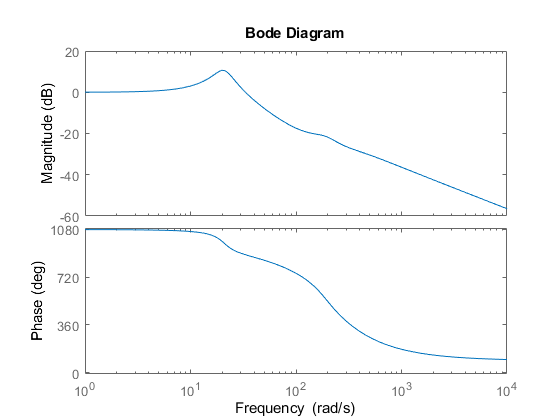

clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant);
eftoggle = 1;

%PI controller
Kp = 15;
Ki = 250;

C_tf = tf([Kp Ki],[1 0]);

%Delay (Pade approximation)
td =0.04;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = d_tf*C_tf*G_plant;
den = (1 + num);
cl_tf = num/den;
bode(cl_tf)